# **Report 2 optimization:**

**Problems:**

Problem 1:

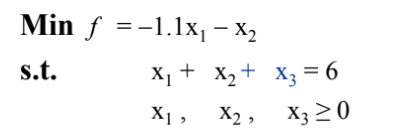

Problem 2:

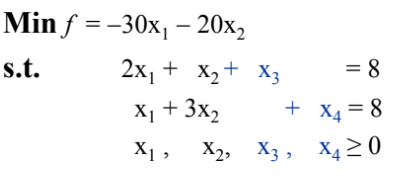

Problem 3:

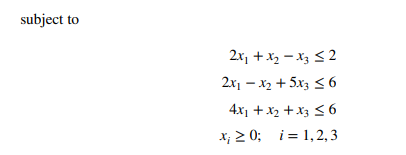

## **Choose type of  initializing the problem,problem number and the problem type:**

Problem=1;
start='Calculated';
choice='Adaptive';

switch Problem
    case 1
        %% objective function:
        c = [-1.1; 
              -1;
               0;];
 
        %% Constraints
         A = [1 1 1];
        % RHS inequalities
         b = [6];
    case 2
        %% objective function:
        c = [-30; 
              -20;
                0;
                0];
 
        %% Constraints
         
         A = [2,1,1,0;
              1,3,0,1];
        % RHS inequalities
         b = [8;8];

    case 3
        %% objective function:
        c = [-1; 
              -2;
               -1;
               0;0;0;];
 
        %% Constraints
         
         A = [2, 1,-1,1,0,0;
              2, -1, 5,0,1,0;
              4, 1 ,1,0,0,1];
        % RHS inequalities
         b = [2;6;6];
end

## Fixed Parameters : step size and centering parameter

alpha = 0.5;
sigma = 0.5;


## Tolerance and iteration number

Acc_error= 1e-6;
%max_iter = 50;

## starting points: Two ways

switch start
    case 'Random'
        [m, n] = size(A);
        x_start=ones(n, 1);
        s_start=ones(n, 1);
    case 'Calculated'
        

s


       % Based on the problem as in the book
       x_start = A'*(((A * A')^-1)*b);
       y_start = ((A * A')^-1 * A * c);
       s_start = c - A' * y_start;
        %non negative
       k=-3/2;
       x_start = x_start + max([0, k * min(x_start) ]);
       s_start = s_start + max([0, k * min(s_start) ]);
       % Approach zero
       x_start = x_start + x_start' * s_start / (2 * sum(s_start));
       s_start = s_start + x_start' * s_start / (2 * sum(x_start));
end
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% %%%%%%%%% First way %%%%%%%%%%%%%%%%%%%
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% % Random values:
% [m, n] = size(A);
% x_start=ones(n, 1);
% s_start=ones(n, 1);
% 
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% %%%%%%%%% Second way %%%%%%%%%%%%%%%%%%%
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% % Based on the problem as in the book
% x_start = A'*(((A * A')^-1)*b);
% y_start = ((A * A')^-1 * A * c);
% s_start = c - A' * y_start;
% %non negative
% k=-2;
% x_start = x_start + max([0, k * min(x_start) / 2]);
% s_start = s_start + max([0, k * min(s_start) / 2]);
% % Approach zero
% x_start = x_start + x_start' * s_start / (2 * sum(s_start));
% s_start = s_start + x_start' * s_start / (2 * sum(x_start));

## **Prints:**

fprintf('Starting point x:\n');

Starting point x:


disp(x_start);

     3
     3
     3



fprintf('Starting point y:\n');

Starting point y:


disp(y_start);

   -0.7000



fprintf('Starting point s:\n');

Starting point s:


disp(s_start);

    0.5000
    0.6000
    1.6000



## **Function Calling**

switch choice
    case 'Fixed'
        [X, S, obj_func,i] = central_path_fixed_step(x_start,y_start,s_start,A, b, c, alpha, sigma, Acc_error);
    case 'Adaptive'
        [X, S, obj_func,i] = central_path_adaptive_step(x_start,y_start,s_start,A, b, c, sigma, Acc_error);
    case 'Merhotra'
        [X, S, obj_func,i] = Merhotra(x_start,y_start,s_start,A, b, c, Acc_error);
end

## **Plotting**

% Display the results and make any necessary plots
fprintf('Optimal solution x:\n');

Optimal solution x:


disp(X);

    3.0000    2.7961    3.2217    4.7884    5.9982    6.0000
    3.0000    2.3301    2.3225    1.1671    0.0016    0.0000
    3.0000    0.8738    0.4558    0.0446    0.0002    0.0000



fprintf('Optimal slack variables s:\n');

Optimal slack variables s:


disp(S);

    0.5000    0.4840    0.0485         0    0.0000         0
    0.6000    0.5840    0.1485    0.1000    0.1000    0.1000
    1.6000    1.5840    1.1485    1.1000    1.1000    1.1000



fprintf('Number of iterations :\n');

Number of iterations :


disp(i);

     5



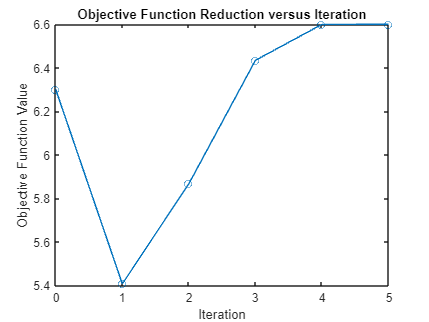


% Plot objective function reduction versus iteration
figure;
plot(0:i,-1* obj_func, '-o');
title('Objective Function Reduction versus Iteration');
xlabel('Iteration');
ylabel('Objective Function Value');

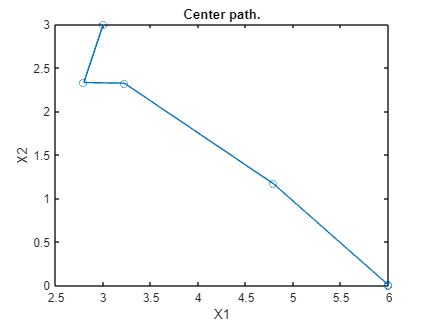



% Plot Center path.
figure;
xlim=0;ylim=0;
plot(X(1,:),X(2,:),'-o')
title('Center path.');
xlabel('X1');
ylabel('X2');

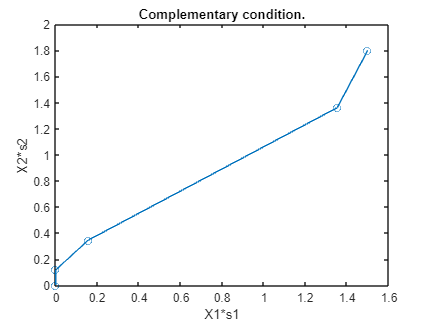


% Plot Complementary condition.
figure;
plot(X(1,:).*S(1,:),X(2,:).*S(2,:),'-o');
title('Complementary condition.');
xlabel('X1*s1');
ylabel('X2*s2');

## **Matlab**

options = optimoptions('linprog','Algorithm','interior-point','Display','iter');
[real_x,real_obj_func,exitflag,output] = linprog(c,A,b,[],[],zeros(length(x_start),1),[],[],options)

LP preprocessing removed 0 inequalities, 0 equalities,
2 variables, and 2 non-zero elements.

 Iter            Fval  Primal Infeas    Dual Infeas  Complementarity  
    0   -3.905000e+00   0.000000e+00   5.100000e+00     2.550000e+00  
    1   -6.588890e+00   0.000000e+00   6.066773e-02     1.009987e-02  
    2   -6.599988e+00   5.115908e-13   3.033387e-05     1.100707e-05  
    3   -6.600000e+00   2.025047e-13   1.516693e-08     5.503538e-09  

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in feasible directions, to within the selected value of the function tolerance, and constraints are satisfied
to within the selected value of the 

real_x =     6.0000
         0
         0


real_obj_func = -6.6000

exitflag = 1

output = struct with fields:
         iterations: 3
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in feasible directions, to within the selected value of the function tolerance, and constraints are satisfied to within the selected value of the constraint tolerance.'
          algorithm: 'interior-point'
    constrviolation: 0
      firstorderopt: 1.5167e-08


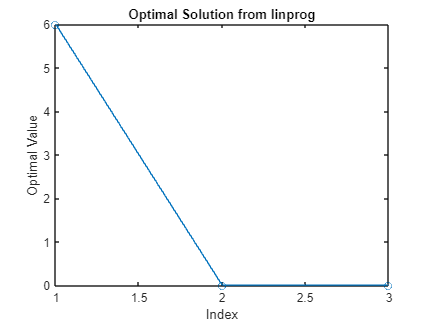

% Plot linprog result
figure;
plot(real_x, '-o');
title('Optimal Solution from linprog');
xlabel('Index');
ylabel('Optimal Value');

## **Functions used**

function [x, s, obj_function,iterations] = central_path_adaptive_step(x_start,y_start,s_start,A, b, c, sigma, tolerance)
    % m=3 , n=2
    [m, n] = size(A);
    iterations=0;

    % Initialization : X,s => n,Y=>m
    x=x_start;
    s=s_start;
    y=y_start;
    
    %y = ones(m, 1);  % Initial dual solution

    %storing objective values in a vector
    obj_function = c'*x_start;
    while sum(x_start.*s_start)>=tolerance
        % Evaluate the primal and dual residuals
        % Primal : Ax=b 
        r_b = A * x_start - b;
        % Dual A^T*Y+s=c
        r_c = A' * y_start + s_start - c;

        % Compute the duality measure
        mu = sum(x_start.*s_start)/n;
        Tau = sigma*mu;

        % jaccobian matrix :
%         jaccobian = [       zeros(n)  A'            eye(n);
%                               A       zeros(m,m)    zeros(m,n);
%                         diag(s)       zeros(n,m)    diag(x)            ];
        jaccobian = [zeros(n),A',eye(n);
             A,zeros(m,m),zeros(m,n);
             diag(s_start),zeros(n,m), diag(x_start)];
        % Right hand side :
        RHS = [-r_c; 
                -r_b;
                -(x_start .* s_start)+Tau];
        % delta x,delta y ,delta s :
        delta_vector=jaccobian\RHS;


        % Extract components of the search direction
        d_x = delta_vector(1:n);
        d_y = delta_vector(n+1:n+m);
        d_s = delta_vector(n+m+1:end);

        alpha_primal=min([1; min(-1*x_start(d_x<0)./d_x(d_x<0))]);
        alpha_dual=min([1; min(-1*s_start(d_s<0)./d_s(d_s<0))]);
        
        % Update the variables 
        x_start = x_start + alpha_primal * d_x;
        y_start = y_start + alpha_dual * d_y;
        s_start = s_start + alpha_dual * d_s;

        %update Sigma
        sigma = sigma*sigma;

        % Update the objective function value
        %obj_function = c' * x_start;
        x = [x , x_start];
        s = [s,s_start];
        obj_function = [obj_function , c' * x_start];
        iterations=1+iterations;

        % Check convergence
    end
end

function [x, s, obj_function,iterations] = Merhotra(x_start,y_start,s_start,A, b, c, tolerance)
    % m=3 , n=2
    [m, n] = size(A);
    iterations=0;
    % Initialization : X,s => n,Y=>m
    x=x_start;
    s=s_start;
    y=y_start;
    
    %y = ones(m, 1);  % Initial dual solution

    %storing objective values in a vector
    obj_function = c'*x;

    while sum(x_start.*s_start)>=tolerance
        % Evaluate the primal and dual residuals
        % Primal : Ax=b 
        r_b = A * x_start - b;
        % Dual A^T*Y+s=c
        r_c = A' * y_start + s_start - c;

        % Compute the duality measure
        mu = sum(x_start.*s_start)/n;
        

        % jaccobian matrix :
%         jaccobian = [       zeros(n)  A'            eye(n);
%                               A       zeros(m,m)    zeros(m,n);
%                         diag(s)       zeros(n,m)    diag(x)            ];
        jaccobian = [zeros(n),A',eye(n);
             A,zeros(m,m),zeros(m,n);
             diag(s_start),zeros(n,m), diag(x_start)];
        % Right hand side :
        RHS = [-r_c; 
                -r_b;
                -(x_start .* s_start)];
        % delta x,delta y ,delta s :
        delta_affine=jaccobian\RHS;


        % Predictor :
        d_x_aff = delta_affine(1:n);
        d_y_aff = delta_affine(n+1:n+m);
        d_s_aff = delta_affine(n+m+1:end);
        %new alpha 
        alpha_primal_aff=min([1; min(-1*x_start(d_x_aff<0)./d_x_aff(d_x_aff<0))]);
        alpha_dual_aff=min([1; min(-1*s_start(d_s_aff<0)./d_s_aff(d_s_aff<0))]);
        %new mu
        Mu_aff= sum((x_start + alpha_primal_aff*d_x_aff).*(s_start + alpha_dual_aff*d_s_aff))/n;
        %new sigma
        sigma_aff = (Mu_aff/mu)^3;

        Tau= sigma_aff*mu;

        %Corrector:
        
        % Right hand side :
        RHS_new = [-r_c;
               -r_b ;
               -(x_start .*s_start) - (d_x_aff.*d_s_aff) + sigma_aff*mu];

        % delta x,delta y ,delta s :
        delta_vector=jaccobian\RHS_new;


        % Extract components of the search direction
        d_x = delta_vector(1:n);
        d_y = delta_vector(n+1:n+m);
        d_s = delta_vector(n+m+1:end);

        N=1;

        alpha_primal=min([1; N*min(-1*x_start(d_x<0)./d_x(d_x<0))]);
        alpha_dual=min([1; N*min(-1*s_start(d_s<0)./d_s(d_s<0))]);

        % Update the variables using the central path direction

        x_start = x_start + alpha_primal * d_x;
        y_start = y_start + alpha_dual * d_y;
        s_start = s_start + alpha_dual * d_s;

        % Update the objective function value
       % obj_function = c' * x_start;
        x = [x , x_start];
        s = [s,s_start];
        obj_function = [obj_function , c' * x_start];
        iterations=iterations+1;
    end
end

function [x, s, obj_function,iterations] = central_path_fixed_step(x_start,y_start,s_start,A, b, c, alpha, sigma, tolerance)
    % m=3 , n=2
    [m, n] = size(A);
    iterations=0;
    % Initialization : X,s => n,Y=>m
    x=x_start;
    s=s_start;
    y=y_start;

    %y = ones(m, 1);  % Initial dual solution

    %storing objective values in a vector
    obj_function=c'*x_start;

    while sum(x_start.*s_start)>=tolerance
        % Evaluate the primal and dual residuals
        % Primal : Ax=b 
        r_b = A * x_start - b;
        % Dual A^T*Y+s=c
        r_c = A' * y_start + s_start - c;

        % Compute the duality measure
        mu = sum(x_start.*s_start)/n;
        Tau = sigma*mu;

        % jaccobian matrix :
        %jaccobian = [       zeros(n,n)  A'            eye(n);
        %                      A       zeros(m,m)    zeros(m,n);
        %                diag(s)       zeros(n,m)    diag(x)            ];
        jaccobian = [zeros(n),A',eye(n);
             A,zeros(m,m),zeros(m,n);
             diag(s_start),zeros(n,m), diag(x_start)];
        % Right hand side :
        RHS = [-r_c; 
                -r_b;
                -(x_start .* s_start)+Tau];
        % delta x,delta y ,delta s :
        delta_vector=jaccobian\RHS;


        % Extract components of the search direction
        d_x = delta_vector(1:n);
        d_y = delta_vector(n+1:n+m);
        d_s = delta_vector(n+m+1:end);

        % Update the variables using the central path direction
        x_start = x_start + alpha * d_x;
        y_start = y_start + alpha * d_y;
        s_start = s_start + alpha * d_s;

        % Update the objective function value
        %obj_function = c' * x_start;

        x = [x , x_start];
        s = [s,s_start];
        obj_function = [obj_function , c' * x_start];
        %sum(x_start.*s_start)
        iterations=iterations+1;
    end
end